# Signal Preprocessing and Feature Extraction for EMI Data

In this MATLAB Live Editor script, we focus on the preprocessing of impedance data, including their location, severity, and sensor number. Our objective is to extract relevant features that can serve as inputs for neural networks and other machine learning algorithms.

# **Chapter 1: Signal Preprocessing**

## Section **1: Loading data**

The first step is to load the required data using the `LoadMatData` function. This function will save the data in a dictionary called `dict`. The severity level of the data can be specified using the variable `sev`, while the window size to be applied to the data can be determined using the variable `win`.

clear
clc
close all
% sev={'3mag','6mag'};
sev={'3mag','6mag'}; %
path='D:\Data\';
obj=Imp();
obj2=PeakFinder();

Selecting the window:

win='tukey';
dict=obj.LoadMatData(path,sev,win);

## Section **2: Initialization**

In this section, we specify the range of frequencies that are suitable for the specific task at hand. Additionally, we define the step size for dividing the frequencies into RMSD (Root Mean Square Deviation) intervals. These initialization steps help to set up the frequency analysis process accurately and efficiently.

range=[30000 80000];
obj.fs=10e6;
% Dim=size(dict('Adm3mag'),2);
% F= obj.fs*((0:floor(Dim-1))/(2*Dim));
F=dict('Freq');
obj.Fnew=F'; 
step=10000;

note: If the signals needs to be in a certain range run this secsion

## Section **3: **Plotting RMSD of Selected Signals

### **3-1 **Plotting Pristine Cases for Different Test Situations

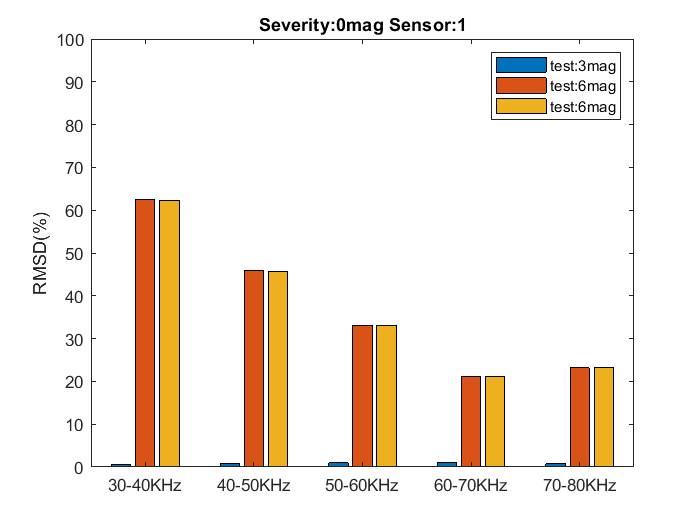

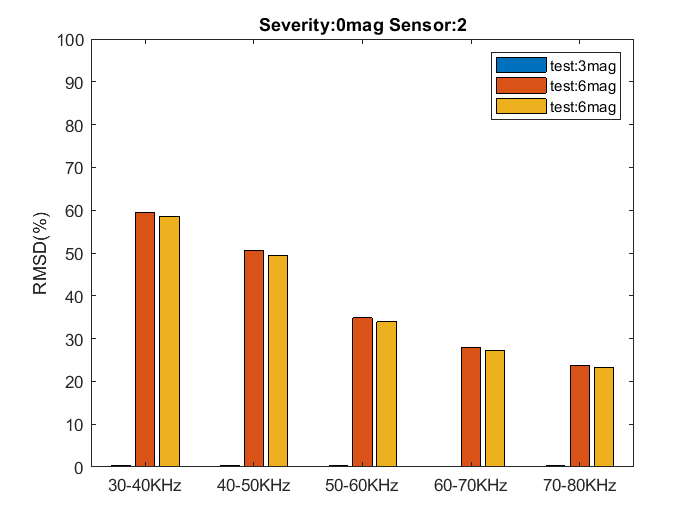

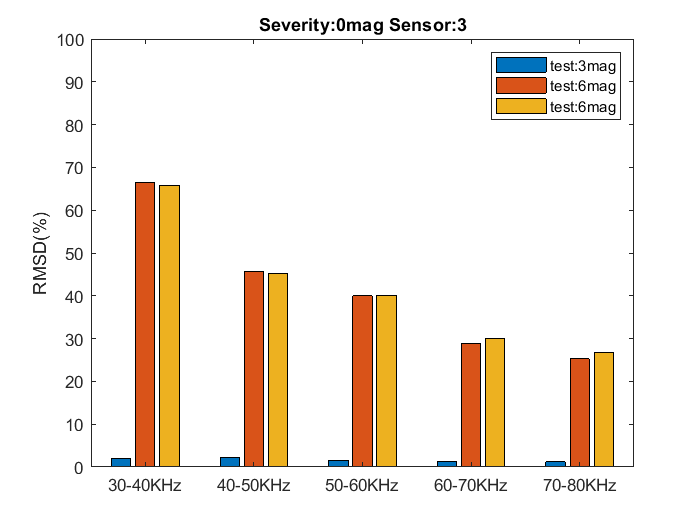

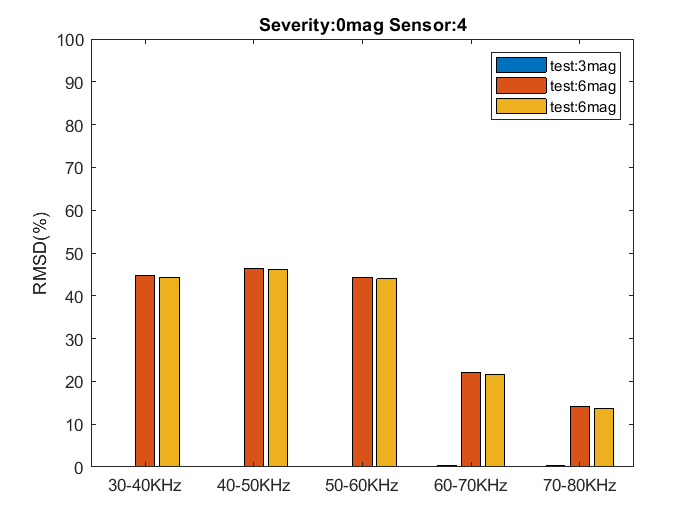

for s=1:4
    figure
    clear Mat sev label
    %     sev={'3mag','6mag','Sev'};
    sev={'3mag','6mag'};
    sensor=s;
    %     Svrty=3;
    %     sev(1:10)={[int2str(Svrty),'mag']};

    for i=1:(2*length(sev)-1)
        label(i)={['test:',sev{(floor(i/2)+1)},'']};
    end
    % mat=RMSDMat(self,sev,loc,sen,dict,sevcell,sample)
    Mat=RMSDMat(obj,zeros(1,length(sev)),zeros(1,length(sev))...
        ,sensor,dict,sev,'0.5-mean');
    title1=['Severity:','0','mag Sensor:',int2str(sensor)];
    Y=plotRMSD(obj,Mat,range,step,Title=title1,Label=label);
    ylim([0 100]);
%     SavePath=['C:\Users\mehrab\Desktop\thesis code\rep\Rep2\S',int2str(s),'DiffTest'];
%     saveas(gcf,SavePath,'jpeg')
end

### 3-2 Plotting RMSD for Different Locations at a Fixed Severity

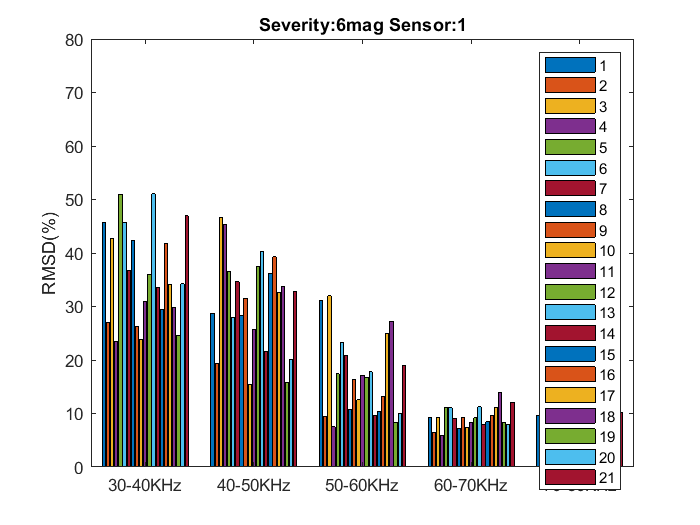

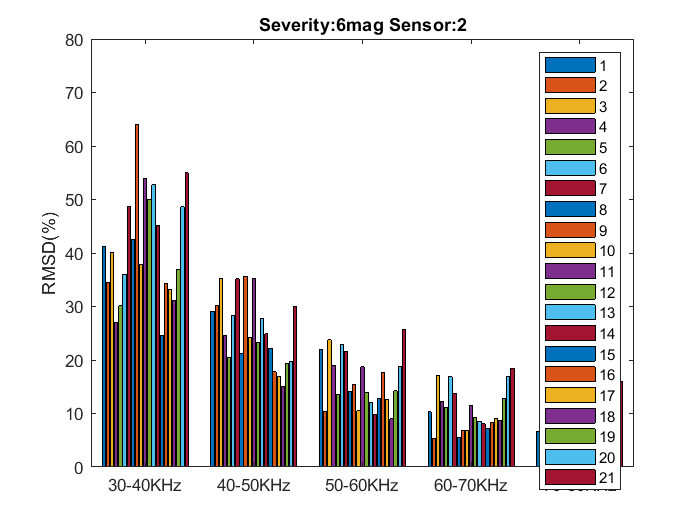

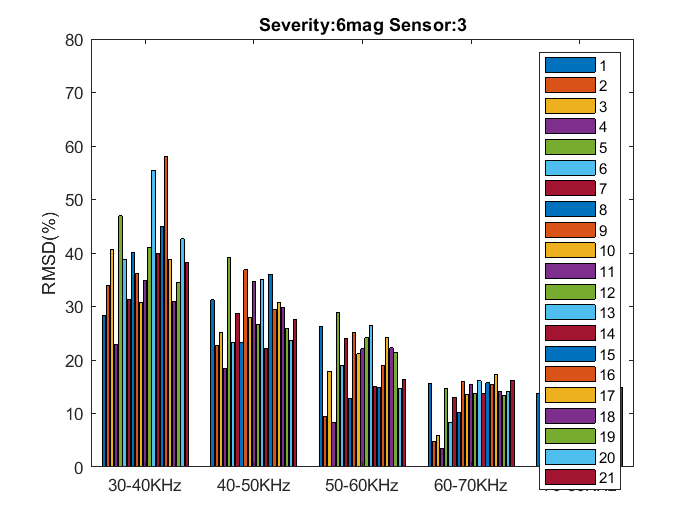

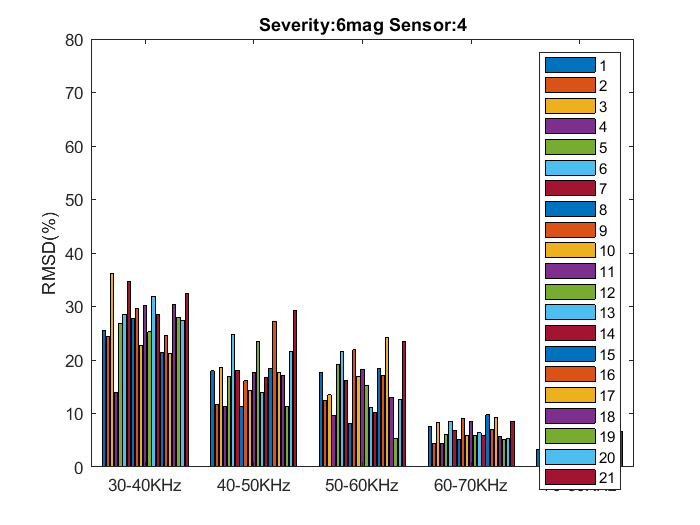

for s=1:4
    figure
    clear Mat sev label
    % sev={'3mag','3mag','6mag','6mag','Sev','Sev'};
    sensor=s;
    Svrty=6;
    step2=1;
    locs=[0:step2:21];
    Llocs=length(locs);
    sev(1:Llocs)={[int2str(Svrty),'mag']};
    for i=1:Llocs-1
        label(i)={int2str(locs(i+1))};
    end
    % mat=RMSDMat(self,sev,loc,sen,dict,sevcell,sample)
    Mat=RMSDMat(obj,[0 ones(1,Llocs)*Svrty],locs,sensor,dict,sev,'mean');
%     Mat2=RMSDMat(obj,0,0,s,dict,{[int2str(Svrty),'mag']},'mean');
%     MatF=[Mat2;Mat];
    title1=['Severity:',int2str(Svrty),'mag Sensor:',int2str(sensor)];
    Y2=plotRMSD(obj,Mat,range,step,Label=label,Title=title1,plot=true);
        ylim([0 80]);
    %     SavePath=['C:\Users\mehrab\Desktop\thesis code\rep\Rep2\',int2str(Svrty),'magS',int2str(s),'diffLocation'];
    %     saveas(gcf,SavePath,'jpeg')
end

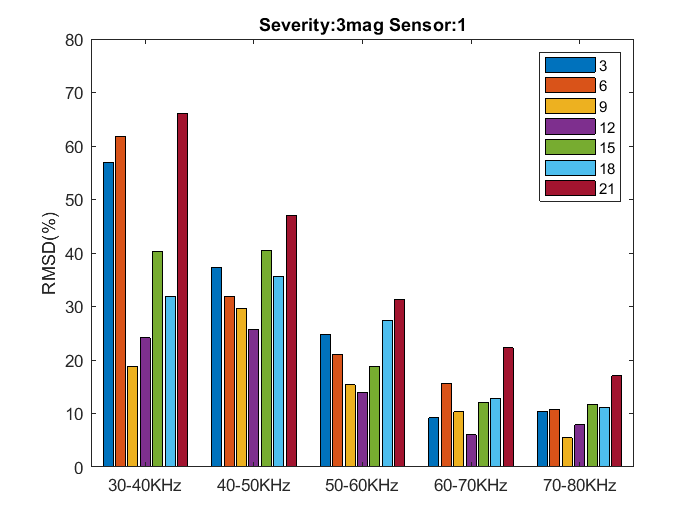

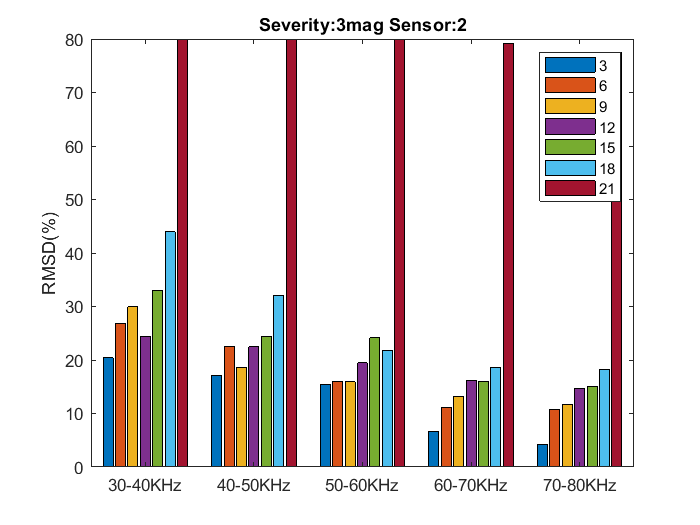

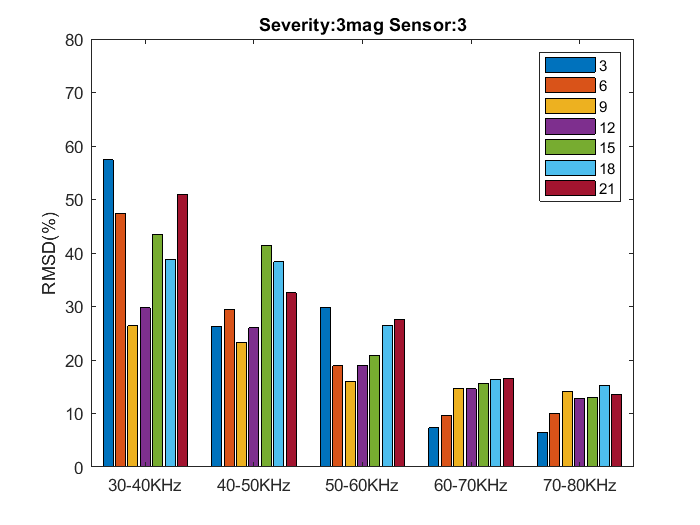

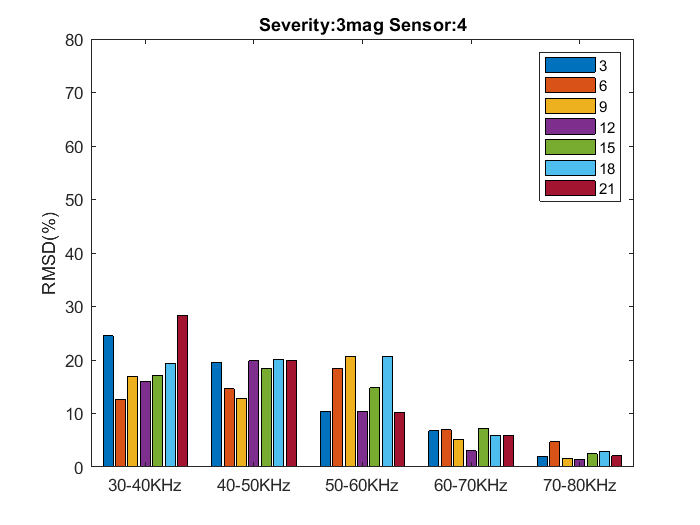

for s=1:4
    figure
    clear Mat sev label
    % sev={'3mag','3mag','6mag','6mag','Sev','Sev'};
    sensor=s;
    Svrty=3;
    step2=3;
    locs=[0:step2:21];
    Llocs=length(locs);
    sev(1:Llocs)={[int2str(Svrty),'mag']};
    for i=1:Llocs-1
        label(i)={int2str(locs(i+1))};
    end
    % mat=RMSDMat(self,sev,loc,sen,dict,sevcell,sample)
    Mat=RMSDMat(obj,[0 ones(1,Llocs)*Svrty],locs,sensor,dict,sev,'mean');
%     Mat2=RMSDMat(obj,0,0,s,dict,{[int2str(Svrty),'mag']},'mean');
%     MatF=[Mat2;Mat];
    title1=['Severity:',int2str(Svrty),'mag Sensor:',int2str(sensor)];
    Y2=plotRMSD(obj,Mat,range,step,Label=label,Title=title1,plot=true);
        ylim([0 80]);
    %     SavePath=['C:\Users\mehrab\Desktop\thesis code\rep\Rep2\',int2str(Svrty),'magS',int2str(s),'diffLocation'];
    %     saveas(gcf,SavePath,'jpeg')
end

## Section 4: Admittance graph for signal comparison

### 4-1 Comparing pristine cases in 3-mag, 6-mag, and severity modes 

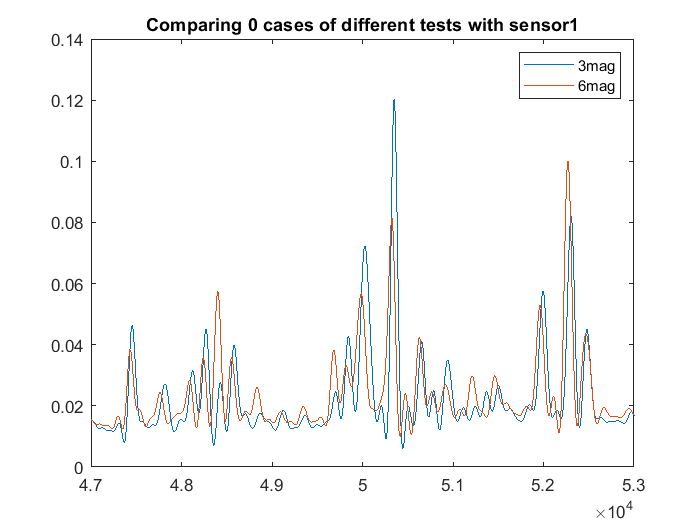

for s=1:1
    figure
    sensor=s;
    sev={'3mag','6mag'};
    % mat=RMSDMat(self,sev,loc,sen,dict,sevcell,sample)
    Mat=RMSDMat(obj,[3,6],[10,10],sensor,dict,sev,'mean');
    %Plotting
    plot(obj.Fnew,Mat)
    a=['Comparing 0 cases of different tests with sensor',int2str(sensor)];
    title(a)
    legend(sev)
    xlim([47000 53000])
    legend
    %Saving file
%     SavePath=['C:\Users\mehrab\Desktop\thesis code\rep\Rep2\Compare0caseS',int2str(s)];
%     saveas(gcf,SavePath,'jpeg')
end

### **4-2 Comparing damaged and pristine cases in 3-mag and 6-mag modes **

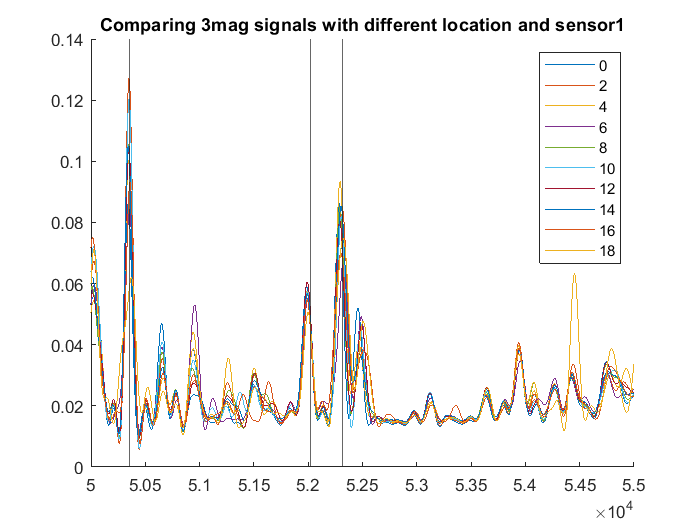

figure
hold on
for s=1

    sensor=s;
    step=2;
    startSignal=0;
    endSignal=18;
    loc=(startSignal:step:endSignal);
    len=length(loc);
    %     sev=repmat({'3mag'},1,5);
    % mat=RMSDMat(self,sev,loc,sen,dict,sevcell,sample)
    sev=repmat({'3mag'},1,len);
    Mat=RMSDMat(obj,[0 ones(1,(len-1))*3],loc,sensor,dict,sev,'mean');
    load('D:\New folder (6)\thesis code\MainCode\BPeaks.mat')
    %Plotting
    plot(obj.Fnew,Mat)
    xline(BestPeaks(s,:))
    a=['Comparing ',sev{1},' signals with different location and sensor',int2str(sensor)];
    title(a)
    legend(arrayfun(@(x) num2str(x),loc, 'UniformOutput', false))
    %     xlim([50000 55000])
    legend
    xlim([50000,55000])
    %Saving file
    %     SavePath=['C:\Users\mehrab\Desktop\thesis code\rep\Rep2\Compare0caseS',int2str(s)];
    %     saveas(gcf,SavePath,'jpeg')
end

### **4-3 Comparing damaged and pristine cases in 3-mag and 6-mag modes **

% for s=1:4
s=1

s = 1

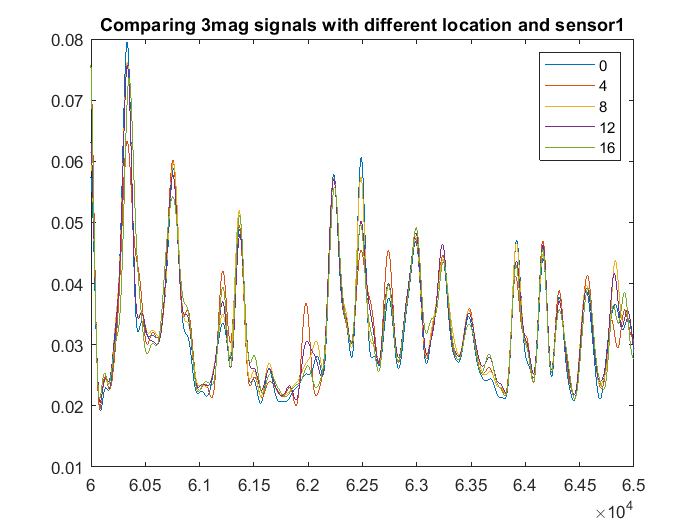

    figure
    sensor=s;
    %     sev=repmat({'3mag'},1,5);
    % mat=RMSDMat(self,sev,loc,sen,dict,sevcell,sample)
    sev=repmat({'3mag'},1,5);
    Mat=RMSDMat(obj,[0 ones(1,4)*3],[0:4:18],sensor,dict,sev,'mean');
    %Plotting
    plot(obj.Fnew,Mat)
    a=['Comparing ',sev{1},' signals with different location and sensor',int2str(sensor)];
    title(a)
    xlim([60000,65000])
    legend(arrayfun(@(x) num2str(x), [0:4:18], 'UniformOutput', false))

    %     xlim([40000 45000])
    legend

    %Saving file
    %     SavePath=['C:\Users\mehrab\Desktop\thesis code\rep\Rep2\Compare0caseS',int2str(s)];
    %     saveas(gcf,SavePath,'jpeg')
% end

## Section 5: Creating Labels for Neural Network (NN) Outputs and Dataset Splitting

In this section, we will create labels for the outputs of the neural network (NN) and split the dataset into training, validation, and test sets. The labels will represent the regions or coordinates of the damages corresponding to the input data.

%Making label for NN outputs and choose for train validation and test dataset
% It can be region or coordinate of the damages
for i=1:3
    locs={[0:18],[19,20,23],[22,21]};
    LabelName={'OutputTrain','OutputVal','OutputTest'};
    FeatureName={'InputTrain','InputVal','InputTest'};
    % for i=1:length(locs)
    % i=3;
    [mapping2,region2]=convertloc(obj2,dict('Loc3mag'),dict('Sev3mag'));
    [mapping,region]=convertloc(obj2,dict('Loc6mag'),dict('Sev6mag'));
    % dict('Label6mag')=mapping;
    % dict('Label3mag')=mapping2;
    dict('Label6mag')=region;
    dict('Label3mag')=region2;
    result=divideData(obj,dict,locs{i},(1:4),[3,6]);


    eval([LabelName{i},'=result("Label");'])
    eval([FeatureName{i},'=result("Label");'])
    % OutputTrain=result('Label');
    % save('PCAClassTask.mat','inputTest','inputTrain','inputVal')
    %     save('PCAClassTask.mat',LabelName{i},FeatureName{i},'-append')
end


# Chapter 2: Feature Extraction

## Section 6: Finding Local Peaks in Signals

In this section, we will employ methods to identify the optimal peaks in our signals. The goal is to determine the most repetitive peaks, which will be utilized as input features for our neural network.

### 6-1 Identify the optimal peaks

% for
Severity=[3,6];
locs={[0,1,3:9,11:14,16,18:23],[2,10,15,17]};
i=1;
% sev={'3mag','6mag'};
% LabelName={'OutputTrain','OutputVal','OutputTest';'inputTrain','inputVal','inputTest'};
[~,region2]=convertloc(obj2,dict('Loc3mag'),dict('Sev3mag'));
[~,region]=convertloc(obj2,dict('Loc6mag'),dict('Sev6mag'));
dict('Label6mag')=region;
dict('Label3mag')=region2;

result=divideData(obj,dict,locs{i},(1:4),Severity);
result('Freq')=dict('Freq');
% clc
[BestPeaks,Widths,prominence,Amplitude,Scores]=FindImpPeaks2...
    (obj2,result,[3,6],locs{i},MaxNum=55,FeatureNum=10,MaxPoints=25000);

% end

### 6-2 Identifying Nearby Peaks Corresponding to Optimal Peaks

File(1)={'D:\Data\3mag\tukeyCut.mat'};
File(2)={'D:\Data\6mag\tukeyCut.mat'};
Severity=[3,6];
locs={[0,1,3:9,11:14,16,18:23],[2,10,15,17]};
modes={'Train','Val','Test'};
for j=1:2
for i=1:length(File)
    % i=1;
    %     clearvars -except File i
    obj2=PeakFinder();
    peaksfile='C:\Users\mehrab\Desktop\thesis code\MainCode\BPeaks3.mat';
    NearestPeaks2(obj2,File{i},peaksfile,Severity(i),locs{j},['LocalPeak',int2str(i*3),'Mag',modes{j},'.mat'])
end
end
% endr

### 6-3 Plotting a Sample Peaks and Highlighting the Best Peaks

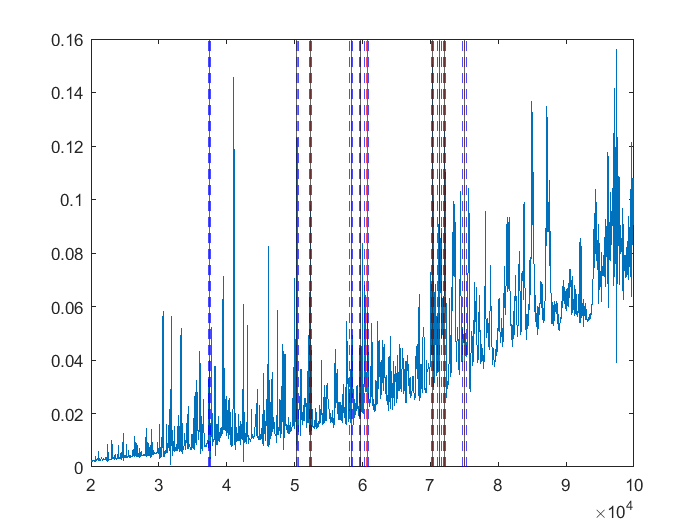

% for s=1:4
s=1;
severities=3;
load(['LocalPeak',int2str(severities),'MagTrain.mat'])
load("BPeaks3.mat")
% obj=Imp();
figure
sensor=s;
i=1;sever=severities;loc=20;
%     sev=repmat({'3mag'},1,5);
% mat=RMSDMat(self,sev,loc,sen,dict,sevcell,sample)
sample=1;
sevcell=repmat({[int2str(severities),'mag']},1,1);
Mat=RMSDMat(obj,sever,loc,sensor,dict,sevcell,sample);
%Plotting
plot(obj.Fnew,Mat)
%     a=['Comparing ',sev{1},' signals with different location and sensor',int2str(sensor)];
%     title(a)
%     legend(arrayfun(@(x) num2str(x), [0:4:18], 'UniformOutput', false))
%     xlim([40000 45000])
% legend
[num, IndTot]=RSampleVal2(obj,s,loc,sever,dict(['Loc',sevcell{i}]),...
    dict(['Sen',sevcell{i}]),dict(['Sev',sevcell{i}]),sample);
xline(BestPeaks(s,:),'--r')
xline(FreqRange(s,:),'--b')
vec=TotalEqPeak(IndTotal==IndTot,:);
% vec(1,:)=EqPeak(s,IndTot,:);
xline(vec)


%Saving file
%     SavePath=['C:\Users\mehrab\Desktop\thesis code\rep\Rep2\Compare0caseS',int2str(s)];
%     saveas(gcf,SavePath,'jpeg')
% end

### 6-4 Preparing Peak Data for Neural Network (NN) Analysis

% locs={[0,1,3:9,11:14,16,18:23],[2,10,15,17]};
clear
vars={'TotalEqProminence','TotalEqPeak','IndTotal','LocTotal','SevTotal','SenTotal'};  %Detremine which vars should be concatenate
modes={'Train','Val','Test'}; %ditemine different type of data
vars2={'PeakProm','PeakFreq','indices','Locs','Sevs','Sens'}; %Output name
obj2=PeakFinder();
for i=1:2
    for k=1:length(vars)
        eval([vars2{k},modes{i},'=[];']);
        for j=1:2
            load(['LocalPeak',int2str(j*3),'Mag',modes{i},'.mat']);
            
%             IndTotal=transpose(IndTotal);
            eval([vars2{k},modes{i},'=[',vars2{k},modes{i},';',vars{k},'];']);

        end
%         eval([vars{k},modes{i},'out=Sorting4NN(obj2,',vars{k},'tot)']);
    end
end

%Sorting data with respect to points of peaks and saving them in a file as
%input of NN
    dd=1;
for i=1:2  %Number of modes

    k=1;
    eval(['Ncol=size(',vars2{k},modes{i},',2);'])
    eval(['inputs',modes{i},'=[];'])
    iii1=1;
    iii2=1;
    for j=1:Ncol
        for k=1:2
            eval(['aa=',vars2{k},modes{i},';'])
            eval(['inputs',modes{i},'=[inputs',modes{i},',aa(:,iii2)];'])
            iii1=iii1+1;
        end
        iii2=iii2+1;
    end
    if(dd==1)
        save('inputsdata.mat',['inputs',modes{i}])
        dd=2;
    else
        save('inputsdata.mat',['inputs',modes{i}],'-append')
        
    end
end

### 6-5 Concatenating optimal peaks Data

% for i=1:lengh
load('inputsdata.mat')
modes={'Train','Val'};
sev={'3mag','6mag'};
locs={[0,1,3:9,11:14,16,18:23],[2,10,15,17]};

LabelName={'OutputTrain','OutputVal','OutputTest'};
FeatureName={'inputTrain','inputVal','inputTest'};
[mapping2,region2]=convertloc(obj2,dict('Loc3mag'),dict('Sev3mag'));
[mapping,region]=convertloc(obj2,dict('Loc6mag'),dict('Sev6mag'));
dict('Label6mag')=region;
dict('Label3mag')=region2;

step=10000;
range=[30000 80000];
for i=1:length(locs)
% for i=1


    result=divideData(obj,dict,locs{i},(1:4),[3,6]);
    eval(['result("Adm")=inputs',modes{i},';'])
    FeatureSize=size(result('Adm'),2);
    result2=FeatureConcat(obj,result,locs{i},(1:4),[0,3,6]);
    NAdm=sortingdict(obj,result2('Adm'),FeatureSize);
    result2('Adm')=NAdm;
        eval([LabelName{i},'=result2("Label");'])
        finalInp=[result2('Adm')];
        eval([FeatureName{i},'=finalInp;'])
    
        if(i==1)
            save('MLPPeaksData.mat',LabelName{i},FeatureName{i})
        else
            save('MLPPeaksData.mat',LabelName{i},FeatureName{i},'-append')
        end
end

for s=1:4
% s=4;
load('LocalPeak3MagTrain.mat')
load("BPeaks.mat")

figure
sensor=s;
i=1;sever=3;loc=20;
%     sev=repmat({'3mag'},1,5);
% mat=RMSDMat(self,sev,loc,sen,dict,sevcell,sample)
sample=1;
sevcell=repmat({'3mag'},1,1);
Mat=RMSDMat(obj,sever,loc,sensor,dict,sevcell,1);
%Plotting
plot(obj.Fnew,Mat)
%     a=['Comparing ',sev{1},' signals with different location and sensor',int2str(sensor)];
%     title(a)
%     legend(arrayfun(@(x) num2str(x), [0:4:18], 'UniformOutput', false))
%     xlim([40000 45000])
% legend
[num, IndTot]=RSampleVal2(obj,s,loc,sever,dict(['Loc',sevcell{i}]),...
    dict(['Sen',sevcell{i}]),dict(['Sev',sevcell{i}]),sample)
xline(BestPeaks(s,:),'--r')
xline(FreqRange(s,:),'--b')
vec(1,:)=EqPeak(s,IndTot,:);
xline(vec)

%Saving file
%     SavePath=['C:\Users\mehrab\Desktop\thesis code\rep\Rep2\Compare0caseS',int2str(s)];
%     saveas(gcf,SavePath,'jpeg')
end

## Section 7: Computing RMSD for Signals with Different Sensors and Severity Levels: Train-Test-Validation Split

In this section, we compute the RMSD metric, which is a common metric used in EMI techniques. The data is split into train, validation, and test dataset, and the RMSD is computed using the `divideData` method. The remaining code pertains to saving the data.

% sev={'3mag','6mag'};
locs={[0,1,3:9,11:16,18:23],[2,10,17]};
LabelName={'OutputTrain3','OutputVal3','OutputTest'};
FeatureName={'inputTrain3','inputVal3','inputTest3'};
[~,region2]=convertloc(obj2,dict('Loc3mag'),dict('Sev3mag'));
[~,region]=convertloc(obj2,dict('Loc6mag'),dict('Sev6mag'));
dict('Label6mag')=region;
dict('Label3mag')=region2;
step=10000;
range=[30000 80000];
for i=1:length(locs)
    result=divideData(obj,dict,locs{i},(1:4),[3,6],range=range,step=step);
    eval([LabelName{i},'=result("Label");'])
    finalInp=[result('Sen'),result('Adm')];
    eval([FeatureName{i},'=finalInp;'])
    % OutputTrain=result('Label');
    %     save('PCAClassTask.mat','inputTest','inputTrain','inputVal')
    
    if(i==1)
        save('RMSDClassTask2.mat',LabelName{i},FeatureName{i})
    else
        save('RMSDClassTask2.mat',LabelName{i},FeatureName{i},'-append')
    end
end


## Section 8: Computing RMSD and Concatenating Data with Similar Location and Severity

sev={'3mag','6mag'};
locs={[0,1,3:9,11:16,18:23],[2,10,17]};
LabelName={'OutputTrain','OutputVal','OutputTest'};
FeatureName={'inputTrain','inputVal','inputTest'};
[mapping2,region2]=convertloc(obj2,dict('Loc3mag'),dict('Sev3mag'));
[mapping,region]=convertloc(obj2,dict('Loc6mag'),dict('Sev6mag'));
dict('Label6mag')=region;
dict('Label3mag')=region2;
step=10000;
range=[30000 80000];
for i=1:length(locs)
% for i=1
    result=divideData(obj,dict,locs{i},(1:4),[3,6],range=range,step=step);
    result2=FeatureConcat(obj,result,locs{i},(1:4),[0,3,6]);
        eval([LabelName{i},'=result2("Label");'])
        finalInp=[result2('Adm')];
        eval([FeatureName{i},'=finalInp;'])
    
        if(i==1)
            save('RMSDClassConcat.mat',LabelName{i},FeatureName{i})
        else
            save('RMSDClassConcat.mat',LabelName{i},FeatureName{i},'-append')
        end
end

## Section 9: Performing PCA with All Data

In this section, we will perform Principal Component Analysis (PCA) using all available data. 

rangeF=[35000,80000];
res=result('Adm');
inx=((rangeF(1)<dict('Freq')) & (dict('Freq')<rangeF(2)));
result('AdmRanged')=res(:,inx);
rawdata=result('AdmRanged');
modualtedData=rawdata*10000;
NormData=modualtedData-mean(modualtedData);
% [U,S,V]=svd(NormData);
% PCAData=NormData*V(:,1:50);
% InputTrain=
% save('NNdataPCA.mat','TestPCAData','-append')
% load('NNdataPCA.mat')

## Section 10: Performing PCA with Average of Different Damage Cases Data

### 10-1 Creating Mean Matrix of Damage Cases for Noise Reduction using PCA

In this section, we will create a mean matrix of damage cases to utilize it for noise reduction using Principal Component Analysis (PCA). The mean matrix will represent the average values of the damage cases and serve as a reference for reducing noise in the dataset.

%Section 1 & 2 should run first

MeanMat=[];
modes={'','Mean'}; jj=1; %jj be used for save and load file of the data. 1 for ...
% getting pca from raw data and 2for average of data
rangeF=[30000,80000];
type={'Train','Val'};
inx=((rangeF(1)<dict('Freq')) & (dict('Freq')<rangeF(2)));
% for sen=1:4
locs={[0,1,3:9,11:14,16,18,19,20,22,23],[2,10,15,17]};
sev={'3mag','6mag'};
FeatureNum=38;
loc=[locs{1},locs{1}];
sev1=[0,ones(1,(length(locs{1})-1))*3];
sev2=[sev1,0,ones(1,(length(locs{1})-1))*6];
sevcell1=repmat({'3mag'},1,length(locs{1}));
sevcell2=[sevcell1,repmat({'6mag'},1,length(locs{1}))];

 ! Run this **ONLY** when you want getting PCA from average of the data !

for sen=1:4
    SenMat=RMSDMat(obj,sev2,loc,sen,dict,sevcell2,'mean');
    SenMat=SenMat(:,inx);
    MeanMat=[MeanMat,SenMat];
end

[~,region2]=convertloc(obj2,dict('Loc3mag'),dict('Sev3mag'));
[~,region]=convertloc(obj2,dict('Loc6mag'),dict('Sev6mag'));
dict('Label6mag')=region;
dict('Label3mag')=region2;

result=divideData(obj,dict,locs{1},(1:4),[3,6],mean=false);
res=result('Adm');
result('Adm')=res(:,inx);
result2=FeatureConcat(obj,result,locs{1},(1:4),[0,3,6]);
% end

**Saving the severity and locations of damages for visualization.**

pcaLocation=result2('Loc');
pcaSeverity=result2('Sev');
save(['D:\New folder (6)\thesis code\MainCode\pcadata',modes{jj},'.mat'],"pcaSeverity","pcaLocation")

### 10-2 Normalizing the data for PCA

if(jj==1)
    [NormTrain,Mdata]=meancentric(obj,result2('Adm'));
elseif(jj==2)
[NormTrain,Mdata]=meancentric(obj,MeanMat);
end
clear result result2 dict

### 10-3 Computing PCA

clear dict
c=1000;
NormData=NormTrain*c;
[U,S,V]=svd(NormData,"econ");

Bases=V;

### 10-4 Visualizing the PCA results

#### Plotting the PCA Variance Results

This plot illustrates the variance of each basis vector and provides a visual representation of the relative magnitudes of the variance scores for each base vector.

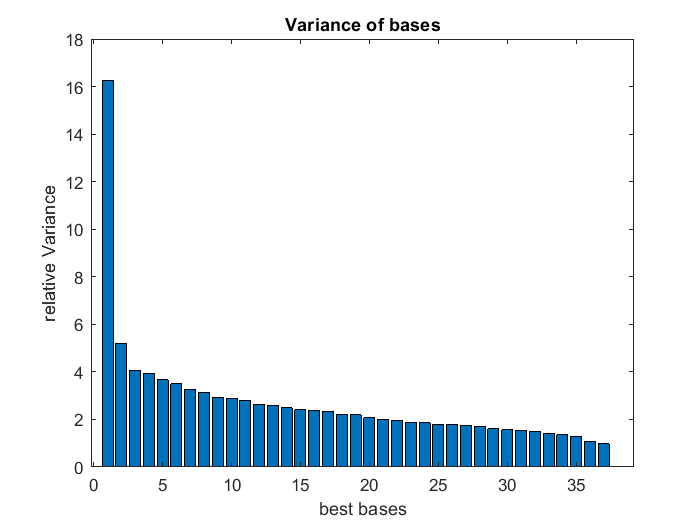

close all
FeatureNum=38;
DS=diag(S);
normDS=DS./sum(DS);
Pnorm=normDS'*100;
% Plot the histogram
bar(Pnorm(1:FeatureNum))
ylabel('relative Variance')
xlabel('best bases')
title('Variance of bases')

save(['D:\New folder (6)\thesis code\MainCode\RawPCAresults',modes{jj},'.mat'],'Bases','S','U','Mdata','c')
save('D:\New folder (6)\thesis code\MainCode\modes.mat','jj','modes','locs','sev','FeatureNum','type')

### 10-5 Constructing a Data Matrix for Dimensionality Reduction

section 1 and 2 should be ran first

% clearvars -except dict Bases obj2 obj Mdata Sdata
load('D:\New folder (6)\thesis code\MainCode\modes.mat')
load(['D:\New folder (6)\thesis code\MainCode\RawPCAresults',modes{jj},'.mat'],'Bases','Mdata','c')

Bbases=Bases(:,1:FeatureNum); %peaking the significant bases
LabelName={'OutputTrain','OutputVal','OutputTest';'inputTrain','inputVal','inputTest'};
[mapping2,region2]=convertloc(obj2,dict('Loc3mag'),dict('Sev3mag'));
[mapping,region]=convertloc(obj2,dict('Loc6mag'),dict('Sev6mag'));
dict('Label6mag')=region;
dict('Label3mag')=region2;
rangeF=[30000,80000];
inx=((rangeF(1)<dict('Freq')) & (dict('Freq')<rangeF(2)));
for i=1:2
    result=divideData(obj,dict,locs{i},(1:4),[3,6]);
    res=result('Adm');
    result('Adm')=res(:,inx);
    %     clearvars -except result Bases locs obj i LabelName Mdata Sdata
    result2=FeatureConcat(obj,result,locs{i},(1:4),[0,3,6]);
    re=result2('Adm');
    modulatedre=re*c;
    NormData=((modulatedre-Mdata));
    FinalFeatures=NormData*Bbases;
    eval([LabelName{1,i},'=result2("Label");'])
    finalInp=FinalFeatures;
    eval([LabelName{2,i},'=finalInp;'])

    if(i==1)
        save(['D:\New folder (6)\thesis code\MainCode\PCARawData'...
            ,modes{jj},'.mat'],LabelName{2,i},LabelName{1,i})

    else
        save(['D:\New folder (6)\thesis code\MainCode\PCARawData'...
            ,modes{jj},'.mat'],LabelName{2,i},LabelName{1,i},'-append')
    end
    pcaLocation=result2('Loc');
    pcaSeverity=result2('Sev');
    save(['D:\New folder (6)\thesis code\MainCode\pcadata',modes{jj},type{i},'.mat'],"pcaSeverity","pcaLocation")
end

### 10-6 Visualizing Data with Two Best Basis Vectors from SVD

In this section, we present the visualization of data after applying the two best basis vectors obtained through Singular Value Decomposition (SVD). By selecting these two basis vectors with the highest significance, we can effectively represent and explore the data in a reduced-dimensional space. This visualization provides insights into the structure, patterns, and relationships present in the data, facilitating a better understanding of its underlying characteristics.

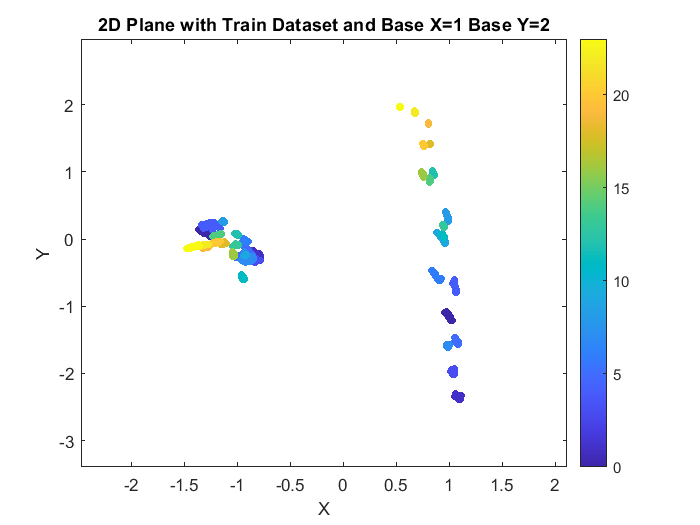

clear
close all
figure
load('D:\New folder (6)\thesis code\MainCode\modes.mat')
jj=1;
load(['D:\New folder (6)\thesis code\MainCode\PCARawData',modes{jj},'.mat'])
load(['D:\New folder (6)\thesis code\MainCode\pcadata',modes{jj},'.mat'])
obj=Imp();
FirstBase=1;
SecondBase=2;
train=true; %determine the dataset that should plot(train or val)

if(train==false)
load(['D:\New folder (6)\thesis code\MainCode\pcadata',modes{jj},type{2},'.mat']);
data=[inputVal(:,[FirstBase,SecondBase]),pcaLocation];
else
data=[inputTrain(:,[FirstBase,SecondBase]),pcaLocation];
load(['D:\New folder (6)\thesis code\MainCode\pcadata',modes{jj},type{1},'.mat']);
end

% Extracting the first and second columns
X = data(:, 1);
Y = data(:, 2);
X=normalizing(obj,X);
Y=normalizing(obj,Y);
plot(X(1),Y(1))
hold on
% Extracting the categorical numbers from the third column
categories = data(:, 3);

% Plotting the 2D plane with colored points
scatter(X, Y, 20, categories, 'filled');
colorbar;
% 
% Adding labels and title


% hold on
% categories = pcaSeverity;
% scatter(x, y, 10, categories);
% legend
% Adjusting axis limits
% xlim([min(X)-1, max(X)+1]);
% ylim([min(Y)-1, max(Y)+1]);
% 
% figure
% sevs=unique(pcaSeverity);
% opt={'o','x','+';'b','r','k'}; %the plot options
% for i=1:sevs
%     hold on;
% i=1;
% j=3;
%     ind=(or((pcaSeverity==sevs(i)),(pcaSeverity==sevs(j))));
% ind=((pcaSeverity==sevs(j)));
%     plot(X(ind), Y(ind), opt{1,i}, 'MarkerSize', 8, 'MarkerFaceColor', opt{2,i});

%     text(X(ind), Y(ind), num2str(categories(ind)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');


% scatter(X(ind), Y(ind), 20, categories, 'filled');
% end
% 
% X=X(ind);
% Y=Y(ind);


xlim([min(X)-1, max(X)+1]);
ylim([min(Y)-1, max(Y)+1]);
legend off
xlabel('X');
ylabel('Y');
title(['2D Plane with ',type{2-train},' Dataset and Base X=',num2str(FirstBase),' Base Y=',num2str(SecondBase)]);

This plot illustrates the evaluation of Principal Component Analysis (PCA) on the dataset, specifically focusing on the top two bases.

The analysis reveals that the first base demonstrates limited sensitivity to changes in the location of damages. However, it exhibits significant sensitivity to the presence of noise in each case. This observation is evident in the plot, where most of the data points exhibit a wide same range of values, indicating the influence of noise.

Conversely, the second base displays less sensitivity to changes in noise levels but is highly responsive to variations in the extent of damages. In the plot, it is apparent that data points within the same damage case exhibit relatively minimal differences. However, when comparing data from different damage cases, distinct variations in values are observed.

## Section 11: Dimensionality Reduction of Peaks Data using PCA

load('MLPPeaksData.mat')

### **11-1 Integrating Optimal Peaks Results with PCA as Input Features(introduction)**

In this section, we will integrate the optimal peaks results with the PCA technique to create a set of input features for our model. The optimal peaks results likely contain valuable information related to damage detection, and combining them with the reduced feature set obtained from PCA can potentially enhance the performance and robustness of our model.

### 11-2 Normalizing data

clear
obj=Imp();
load('MLPPeaksData.mat')
[NormTrain,MeanTrain,NormVal]=meancentric(obj,inputTrain,inputVal);

### 11-3 Perform SVD

[U,S,V]=svd(NormTrain);
save('PCAforPeaks.mat','U','S','V')
inputTrain=NormTrain*V;
inputVal=NormVal*V;

### 11-4 Saving the peaks features after applying PCA

LabelName={'OutputTrain','OutputVal','OutputTest'};
FeatureName={'inputTrain','inputVal','inputTest'};

for i=1:2
    if(i==1)
        save('MLPPeaksPCA.mat',LabelName{i},FeatureName{i})
    else
        save('MLPPeaksPCA.mat',LabelName{i},FeatureName{i},'-append')
    end
end

## Section 12: Feature Extraction for CNN Input

In this section, our focus is on extracting crucial features to feed into our Convolutional Neural Network (CNN). The objective is to create a succinct representation of sensor data for effective damage detection. We achieve this by extracting sensitive features from each sensor and combining them into a 4 by n matrix, where 4 denotes the number of sensors and n represents the selected features.

However, we encounter a challenge with the CNN algorithm when dealing with different types of features in each sample. If we use non-uniform features, the algorithm may struggle to identify suitable filters that can be applied across all features. For example, combining PCA and RMSD data might not yield significant differentiation as a useful filter. Instead, utilizing raw data and applying max/mean pooling before applying filters proves more promising. This approach increases the likelihood of finding filters that can detect peaks and other patterns in Impedance data effectively.

Moreover, max and mean pooling are well-established operators in CNN literature, widely used and proven effective in numerous applications.

The decision to perform feature extraction is motivated by the concern of having a large number of input features if we directly utilize the raw data for the CNN. Without feature extraction, we would have approximately 4*10,000 input features, significantly increasing the model's parameters and making it more susceptible to overfitting.

Considering the limited size of our dataset, using a large number of input features could lead to overfitting issues. Therefore, the feature extraction step helps us create a more efficient and effective model by reducing the number of input features while still retaining critical information for damage detection.

### 12-1 Creating a 3D data tensor

in this part we should create a 3D tesnor as the CNN inputs. 

the dimesion of the tensor is: (#sensors,#reduced_data_dim,#samples)


LabelName={'OutputTrain','OutputVal','OutputTest';'inputTrain','inputVal','inputTest'};
[mapping2,region2]=convertloc(obj2,dict('Loc3mag'),dict('Sev3mag'));
[mapping,region]=convertloc(obj2,dict('Loc6mag'),dict('Sev6mag'));
locs={[0,1,3:9,11:14,16,18,19,20,22,23],[2,10,15,17]};
dict('Label6mag')=region;
dict('Label3mag')=region2;
rangeF=[30000,80000];
inx=((rangeF(1)<dict('Freq')) & (dict('Freq')<rangeF(2)));

for i=1:2
    result=divideData(obj,dict,locs{i},(1:4),[3,6]);
    res=result('Adm');
    result('Adm')=res(:,inx);
    result2=FeatureConcat(obj,result,locs{i},(1:4),[0,3,6],tensor='cubic');
    clear result
    re=result2('Adm');
    eval([LabelName{1,i},'=result2("Label");'])
    eval([LabelName{2,i},'=re;'])

    if(i==1)
        save('D:\New folder (6)\thesis code\MainCode\CNNdataset.mat',LabelName{2,i},LabelName{1,i})

    else
        save('D:\New folder (6)\thesis code\MainCode\CNNdataset.mat',LabelName{2,i},LabelName{1,i},'-append')
    end
end

### 12-2 Admmitance signal visualization for estimating the initial first pooling layer size

In most CNN architectures, the first layer is typically the filter layer, followed by the pooling layer. This sequencing is often justified by the assumption that the optimum algorithm can first utilize a pooling layer to reduce the data size before applying filters. The reason this approach works is that the first filters in the layer can be designed by an optimization algorithm in a way that has no impact on the inputs. However, if the optimum algorithm requires filters to be applied first, the first layer must contain filters rather than a pooling layer. it is not possible to apply the pooling layer before the filter layer for this requirement because the pooling layer cannot be designed to be ignored by the optimization algorithm. 

In this part of the section, we visualize an admittance signal using various max-pooling layers to estimate the initial size of the first pooling layer.

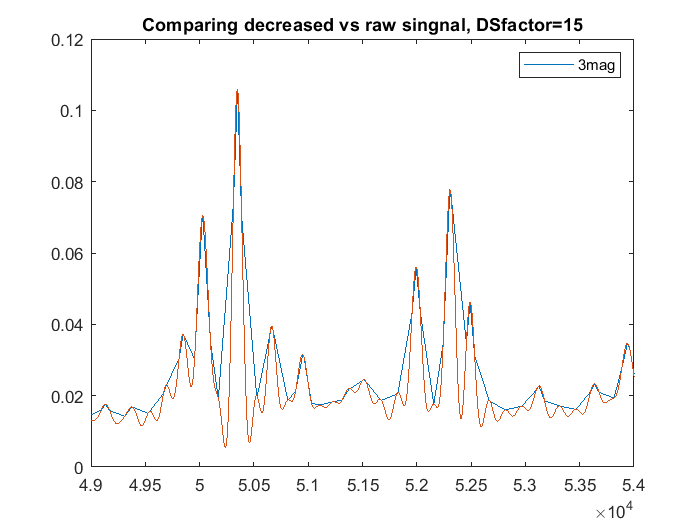

figure
sensor=1;
sev={'3mag'};
rangeF=[30000,80000];
inx=((rangeF(1)<dict('Freq')) & (dict('Freq')<rangeF(2)));
downsampling_factor=15;
freq=obj.Fnew(inx);
Mat=RMSDMat(obj,[3],[10],sensor,dict,sev,'mean');
data=zeros(1,1,length(freq));
data(1,1,:)=Mat(inx);
[downsampled_data_max, f_down] = downsample_max(obj,data, downsampling_factor,freq);
plot(f_down(:),downsampled_data_max(:))
hold on
plot(freq,data(:))

a=['Comparing decreased vs raw singnal, DSfactor=',int2str(downsampling_factor)]; 
xlim([49000,54000])
title(a)
legend(sev)

### 12-3 Visualizing by usning average in each step

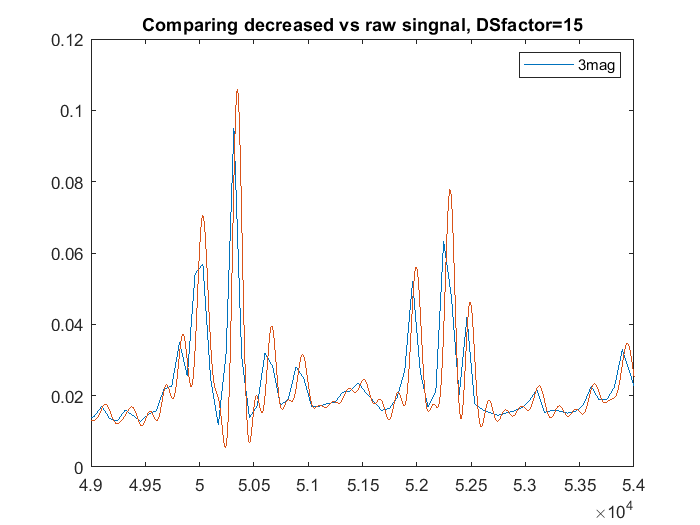

figure
sensor=1;
sev={'3mag'};
rangeF=[30000,80000];
inx=((rangeF(1)<dict('Freq')) & (dict('Freq')<rangeF(2)));
downsampling_factor=15;
freq=obj.Fnew(inx);
Mat=RMSDMat(obj,[3],[10],sensor,dict,sev,'mean');
data=zeros(1,1,length(freq));
data(1,1,:)=Mat(inx);
[downsampled_data_max, f_down] = downsample_mean(obj,data, downsampling_factor,freq);
plot(f_down(:),downsampled_data_max(:))
hold on
plot(freq,data(:))

a=['Comparing decreased vs raw singnal, DSfactor=',int2str(downsampling_factor)]; 
xlim([49000,54000])
title(a)
legend(sev)